addpath("functions/");

# Simulation

save_to_file = false;


L = 50;
wait = 10e2;

save_cycles = 5;
steps = 10e2;

model = @Manna;




% First iteration
if exist('z','var') && exist('avalanche_sizes','var')
	[event_size,event_duration,z] = model(L,steps,0,z);
	avalanche_duration = [avalanche_duration; event_duration];
	avalanche_sizes = [avalanche_sizes; event_size];
elseif exist('avalanche_sizes','var')
	[event_size,event_duration,z] = model(L,steps,wait);
	avalanche_sizes = [avalanche_sizes; event_size];
	avalanche_duration = [avalanche_duration; event_duration];
else
	[avalanche_sizes,avalanche_duration,z] = model(L,steps,wait);

end

% Save to file if the box was checked
timestamp = datestr(now,'mm-dd_HH-MM');
model_str = func2str(model);
filename = sprintf('data/%s_data_%s.mat',model_str,timestamp);


if save_to_file
	s = struct("avalanche_sizes",avalanche_sizes,"avalanche_duration", ...
		avalanche_duration,"z",z,"L",L, ...
		"steps",steps,"wait",wait,"save_cycles",save_cycles, ...
		"z_c",3,"q",4,"model_str",model_str);
	save(filename, "-fromstruct",s);
end

% Post-thermalization loop
parfor iter = 1:save_cycles-1

	[event_size,event_duration,~] = model(L,steps,0,z)

	s = struct("event_size",event_size,"event_duration",event_duration, ...
		"timestamp",timestamp,"iter",iter);
	save(sprintf("data/temp_%s_%d",timestamp,iter),"-fromstruct",s);

	sprintf("Completed save cycle %d out of %d",iter+1,save_cycles)

end

ans = 
    "Completed save cycle 3 out of 5"
ans = 
    "Completed save cycle 2 out of 5"
ans = 
    "Completed save cycle 5 out of 5"
ans = 
    "Completed save cycle 4 out of 5"


[avalanche_sizes,avalanche_duration] = consolidate_temp_data(avalanche_sizes,avalanche_duration,"data/",timestamp);

ans = "Consolidated and deleted temp_08-29_14-52_1.mat"

ans = "Consolidated and deleted temp_08-29_14-52_2.mat"

ans = "Consolidated and deleted temp_08-29_14-52_3.mat"

ans = "Consolidated and deleted temp_08-29_14-52_4.mat"

if save_to_file
	s = struct("avalanche_sizes",avalanche_sizes,"avalanche_duration",avalanche_duration);
	save(filename, "-fromstruct",s,"-append");
end

# Post processing and plotting

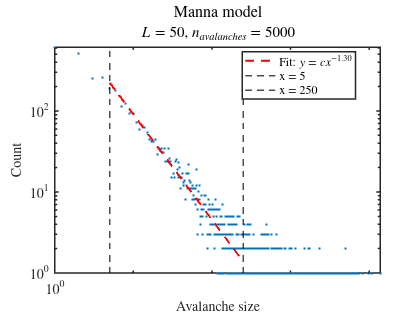

addpath("functions/");

data_str = "avalanche_duration";
data = eval(data_str);

if ~exist(data_str,'var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/Manna_data_08-28_20-49.mat"); end

[X, count] = postprocess_data(data);
subtitle = "$L = "+L+"$, $n_{avalanches} = "+numel(data)+"$";
[fig,tau] = plot_avalanches(X,count,5,250,model_str+" model",subtitle,data_str);